# ViconExtract main

run to open gui with vesettings

MATLAB Live because it looks cleaner

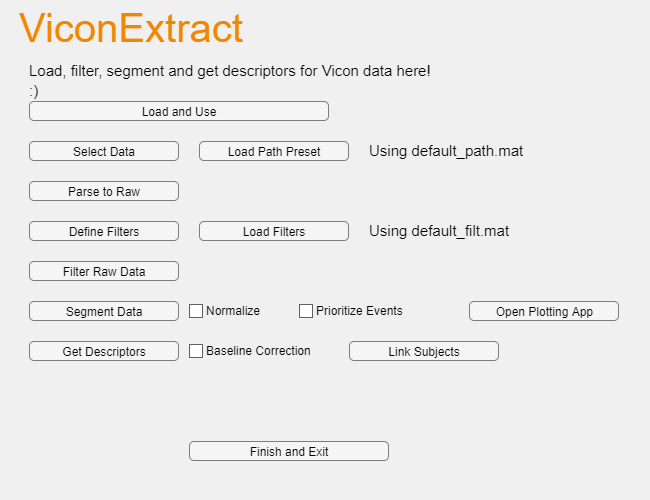

addpath(genpath(pwd));  % PWD maximum depth is ...\viconExtract to run
vesettings = importsettings();
ve_gui = ViconExtract_gui();

Runtime settings

function vesettings = importsettings()
    vesettings = struct('dontuse', 'dontuse');

% GENERAL SETTINGS SECTION
    % Fields which indicate Vicon data
    vesettings.Viconfields = {'ForcePlate', 'Markers', 'JointAngle', 'JointVelocity', 'JointMoment', 'JointForce', 'JointPower', 'SubjectDetails'};
    
    % Vicon Data that is side independent (Left/Right)
    vesettings.side_indep = ["Events", "Markers"];

    % Vicon Data that can be normalized (usually comes normalized by weight from Vicon)
    vesettings.can_norm = ["JointMoment", "JointForce", "JointPower"];

    % Vicon Data with XYZ components
    % Full data name(name_cell) can contain any of the following string
    vesettings.xyz_list = ["Force", "Moment", "CoP", "Angle", "Velocity", "Power"];

    % Vicon sampling frequency
    vesettings.vicon_freq = 100; % Hz

    % number of points for interpolation (see segment_strides.mlx, get_descriptors.mlx)
    vesettings.n_interp = 100;  % default is 100;

    % segmentation z-score threshold for stride outlier removal (see GRFsdegment_plus.mlx)
    vesettings.zscoremax = 3;   % default is 3

    % Eventsegment alignment search radius (see Eventsegment.mlx)
    vesettings.align_search_rad = 10; % default is 10

    % Epoch Generation Settings (see generate_epochs.mlx)
    vesettings.epochwidth = 10; % strides per epoch
        % settings to -1 forces each epoch to include all previous strides

    vesettings.stepsize = 10;   % skip every nth stride for next epoch
        % settings to -1 forces 1 epoch for whole dataset

    % Epoch Generation Units. Either "strides", "frames", or "seconds"
    vesettings.epochwidthunits = "seconds";
    vesettings.stepsizeunits = "seconds";

    % Quantities which can be corrected by a baseline
    vesettings.baselinecorrectables = ["JointMoment", "JointForce", "JointPower"];

    % Vicon units for force, moment, power
    vesettings.getunits = getunits_maker('mm', 'mm/s', 'degrees', 'N', 'N*mm', 'W');    % Units NEED to be chars

% OVERRIDES SECTION ~~~ Altering settings could change behavior significantly

    % import_override allows loading of unknown/invalid .mat files
    vesettings.import_override = false;     % default is false

    % forceplatez_override forces program to use existing forceplate_force_z for segmentation
    % override may cause unintended/faulty behavior from GRFSegment_plus
    vesettings.forceplatez_override = true;    % default is true
    
    vesettings = rmfield(vesettings, 'dontuse');
end

function fun = getunits_maker(distanceunits, velocityunits, angleunits, forceunits, momentunits, powerunits)
    % Returns function handle for attributing correct units given dataname
    fun = @getunits;

    function unitstring = getunits(datastring, normalized)
        % Finds correct units given datastring with normalization
        % Units defined when creating function using getunits_maker
        datastring = lower(datastring);

        if contains(datastring, 'marker')
            unitstring = distanceunits;
            can_normalize = false;
        elseif contains(datastring, 'velocity')
            unitstring = velocityunits;
            can_normalize = false;
        elseif contains(datastring, 'angle')
            unitstring = angleunits;
            can_normalize = false;
        elseif contains(datastring, 'force')
            unitstring = forceunits;
            can_normalize = ~contains(datastring, 'forceplate');
        elseif contains(datastring, 'moment')
            unitstring = momentunits;
            can_normalize = true;
        elseif contains(datastring, 'power')
            unitstring = powerunits;
            can_normalize = true;
        else
            unitstring = 'UNKNOWN';
            can_normalize = false;
        end
        
        % Normalize units if normalized
        if normalized && can_normalize
            unitstring = [unitstring '/kg'];
        end
    end
end